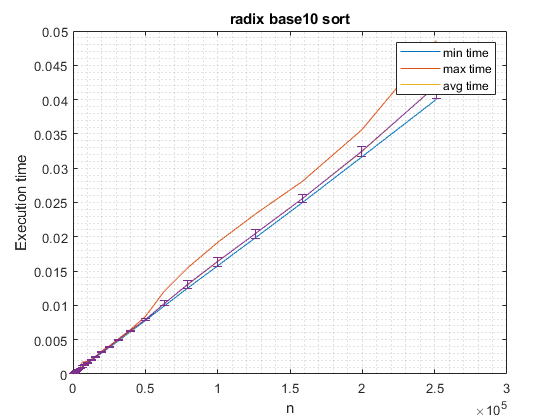

sorts = ["bubble","heap","insertion","merge","quick","radix_base10","rank","selection","shaker","shell"];

s = 6;                                                          % escolher posição do sort no array k se pretende avaliar 

results = load(strcat("./sorts/",sorts(s),"_sort"));

for k = 2:4
    plot(results(:,1),results(:,k));
    hold on;
end

errorbar(results(:,1),results(:,4),results(:,5));               % std dev no avg time

hold off;
grid("minor");
xlabel("n");
ylabel("Execution time");
legend("min time","max time","avg time");
title(strrep(strcat(sorts(s),"_sort"),"_"," "));